# Gabriel Colangelo

clear
close all
clc

## Problem 3a)

Find: $a,p,e,i,\Omega,\omega,\theta^*,(t-t_p)$

Assume: Mass of Chronos is negligble compared to mass of Sun. 1 month = 30.44 days (365.25 days/12 months). Type 1 orbital arc

% Sun Parameters
AU          = 149597898;
mu_sun      = 132712440017.99;

% Right Acensions
lambda_1    = 43.7;
lambda_2    = 62.4;

% Declinations
delta_1     = 33.9;
delta_2     = 48.2;

% Radial Distances
r1          = 1.83*AU;
r2          = 3.15*AU;

% Time between locations
dt          = 3.26*(365.25/12)*24*3600;

% Determine position vectors in Sun centered mean J2000
r1_I        = r1*[cosd(delta_1)*cosd(lambda_1); cosd(delta_1)*sind(lambda_1);sind(delta_1)];
r2_I        = r2*[cosd(delta_2)*cosd(lambda_2); cosd(delta_2)*sind(lambda_2);sind(delta_2)];

% Calculate transfer angle
TA          = acosd(dot(r1_I,r2_I)/(r1*r2));

% Calculate Chord
c           = sqrt(r1^2 + r2^2 - 2*r1*r2*cosd(TA));

% Semi perimeter
s           = (r1 + r2 + c)/2;

% Parabolic time of flight
TOF_par     = (1/3)*sqrt(2/mu_sun)*(s^(3/2) - (s - c)^(3/2));

% Initialize TOF 
TOF         = 0;

% Initialize counter
count       = 0;

% Initial Guess
a_min       = -(r1+c)/2;
a_max       = -20*s;

while (abs(TOF  - dt) > 1e-6) 

    % Choose initial max sma
    a       = (a_min + a_max)/2;
    
    % Initial alpha and beta
    alpha0  = 2*asinh(sqrt(s/(2*abs(a))));
    beta0   = 2*asinh(sqrt((s-c)/(2*abs(a))));

    % 1H Type Transfer Quad Check
    alpha   = alpha0;
    beta    = beta0;
    
    % Lambert Equation
    TOF     = sqrt(abs(a)^3/mu_sun)*((sinh(alpha) - alpha) - (sinh(beta) - beta));

    if TOF < dt
        a_min = a;
    else
        a_max = a;
    end

    % Increment counter 
    count = count + 1;

    if count > 5000
        disp('Max iterations reached')
        break
    end

end

fprintf('The semi major axis of the new Chronos orbit is %.2f km',a)

The semi major axis of the new Chronos orbit is -5835477580.20 km


$$\bar{r}_i = r_i \ [\cos{\delta}\cos{\lambda} \ \hat{x} + \cos{\delta}\sin{\lambda} \ \hat{y} + \sin{\delta} \ \hat{z}]\\ 
\bar{r}_1 = 1.6428 \times 10^8 \ \hat{x} + 1.5699 \times 10^8 \ \hat{y} +  1.5269 \times 10^8 \ \hat{z}  \ [km] \\
\bar{r}_2 = 1.4552 \times 10^8 \ \hat{x} + 2.7835 \times 10^8 \ \hat{y} +  3.5129 \times 10^8 \ \hat{z}  \ [km] \\
\cos{(TA)} = \frac{\bar{r}_1 \cdot \bar{r}_2}{|\bar{r}_1||\bar{r}_2|}\\
TA = 19.9802, 340.0198\ [deg] \\
\text{Type 1, TA < 180:  } \ TA = \phi = 19.9802 \ [deg] \\
\text{Law of cosines from space triangle: } \ c^2 = r_1^2 + r_2^2 - 2r_1r_2\cos{\phi} \\
\text{Semi-perimeter: } \ s = (r_1 + r_2 + c)/2\\
\text{Parabolic time of flight equation for type 1: } \ TOF_{par} = \frac{1}{3}\sqrt{\frac{2}{\mu}}[s^{3/2} - (s-c)^{3/2}] =  100.822 \ [days] = 3.31 \ [months] \\$$


The parabolic time of flight is greater than the change in time, therefore the orbit type is hyperbolic (1H). 

For a type 1H, the true $\alpha$ and $\beta$ values are related to their principal values through:


$$\alpha = \alpha_0\\
\beta = \beta_0$$


Lamberts problem is solved numerically for $a$ using a bisection method:


$$\beta_0= 2\sinh^{-1}{\sqrt{\frac{s-c}{2|a|}} \\
\alpha_0= 2\sinh^{-1}{\sqrt{\frac{s}{2|a|}} \\
TOF = \sqrt{\frac{|a|^3}{\mu}}[(\sinh{\alpha} - \alpha) - (\sinh{\beta} - \beta)] = 3.26 \ [months]  = 99.22 \ [days]\\
\\
\underline{\mathbf{a =  -5.8355 \times 10^9\ [km] = -39.008 \ [AU] }}$$


% Calculate semi latus rectum
p           =  max((4*abs(a)*(s - r1)*(s - r2)/c^2)*...
              [sinh((alpha + beta)/2)^2, sinh((alpha - beta)/2)^2]);
fprintf('The semi latus rectum of the transfer ellipse is %.3f km', p)

The semi latus rectum of the transfer ellipse is 213110897.415 km


$$\alpha  = 0.40668 \\
\beta = 0.29499\\
p = |a|(e^2 - 1) = \frac{4|a|(s-r_1)(s-r_2)}{c^2}\sinh^2{(\frac{\alpha \pm \beta}{2})} = 2.131 \times 10^8 \ [km] \ \text{or} \ 0.0519 \times 10^8 \ [km] \\
\bar{OF} = 2|a|e$$


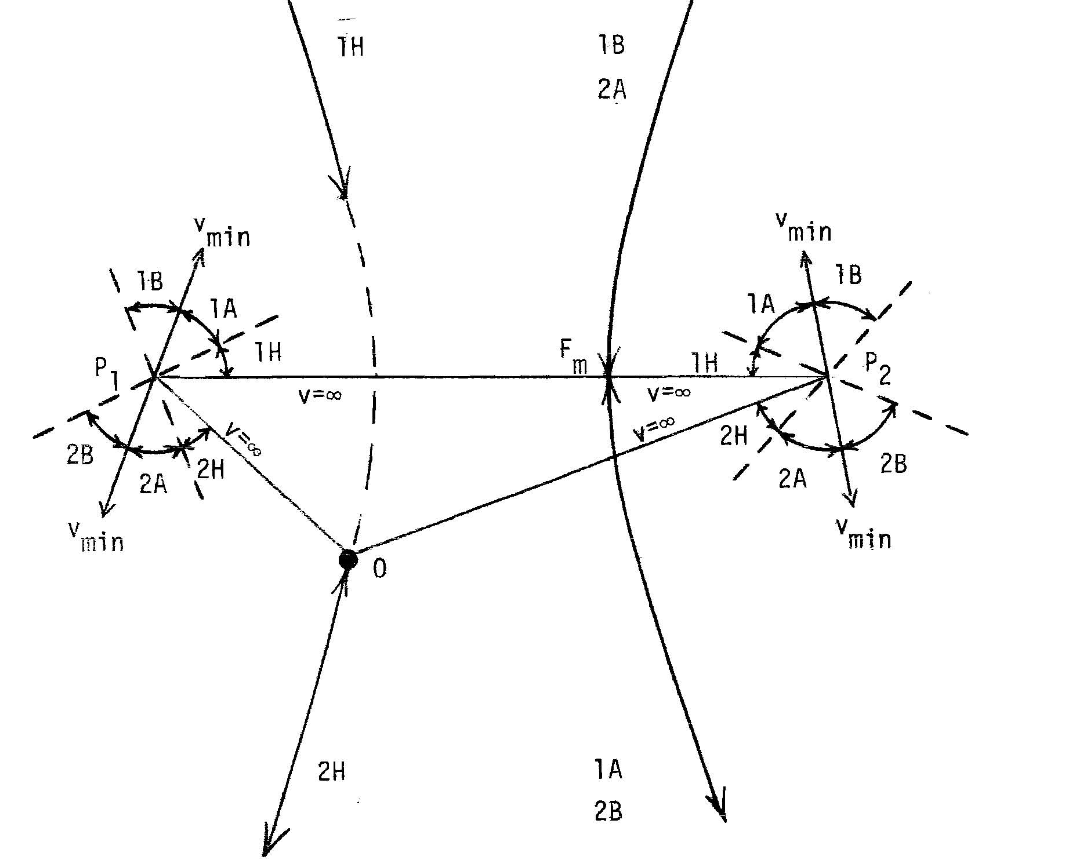

For 1H transfer type, a larger e is needed as observed in the solution space diagram above. A larger e will cause an increase in semi-latus rectum. Therefore, the necessary semi-latus rectum value is the larger option.


$$\underline{\mathbf{p = 2.1311 \times 10^8 \ [km] }}$$


% Eccentricity
e       = sqrt(p/abs(a) + 1);
fprintf('The eccentricity of the Chronos new orbit is %.4f',e)

The eccentricity of the Chronos new orbit is 1.0181


$$p = |a|(e^2 - 1) \\
e = \sqrt{\frac{p}{|a|} + 1}\\
\\
\underline{\textbf{e = 1.0181}}$$


% Angular momentum unit vector
h_hat   = cross(r1_I,r2_I)/norm(cross(r1_I,r2_I));

% Calculate inclination
i       = acosd(h_hat(3));
fprintf('The inclination of Chronos orbit is %.3f deg',i)

The inclination of Chronos orbit is 58.728 deg


$$\hat{h} = \frac{ \bar{r}_1 \times \bar{r}_2 }{| \bar{r}_1 \times \bar{r}_2|} = \sin{\Omega}\sin{i}\  \hat{x} -\cos{\Omega}\sin{i} \ \hat{y} + \cos{i} \ \hat{z} = 0.2869 \hat{x} - 0.8051 \hat{y} + 0.5191 \ \hat{z} \\ 


i = \pm \cos^{-1}{0.5191} = \pm 58.73 \ [deg]  \text{ - Choose positive value} \\
\\
\underline{\textbf{i = 58.73 [deg]}$$


% Calculate RAAN
RAAN    = atan2d(h_hat(1),-h_hat(2));
fprintf('The RAAN of Chronos orbit is %.3f deg',RAAN)

The RAAN of Chronos orbit is 19.614 deg


$$\Omega = \tan^_{-1}{\frac{\sin{\Omega}\sin{i}}{\cos{\Omega}\sin{i}}} = \tan^{-1}{\frac{0.2869}{0.8051} \ \text{based off of the signs of numerator and denominator, must be in quadrant 1.}\\
\\
\underline{\mathbf{\Omega = 19.61 \ deg]}}$$


% F and G Equations
f           = 1 - (r2/p)*(1 - cosd(TA));
g           = (r2*r1)*sind(TA)/sqrt(mu_sun*p);

% Initial velocity in inertial coordinates
v1_I        = (r2_I - f*r1_I)/g;

% Calculate true anomaly
theta_star1 = sign(dot(r1_I,v1_I))*acosd((1/e)*(p/r1 - 1));
theta_star2 = acosd((1/e)*(p/r2 - 1));


$$\bar{r}_2 = f \bar{r}_1 + g \bar{v}_1 \\
f = 1 - \frac{r_2}{p}(1 - \cos{(TA)}), \text{ where } \ TA = \theta^*_2 - \theta^*_1. \ \ f = 0.8669 \\
g  = \frac{r_2r_1}{\sqrt{\mu p}}\sin{(TA)} = 8.288 \times 10^6 \ [s]\\
\bar{v}_1 = \frac{\bar{r}_2 - f \bar{r}_1}{g} = 0.3744 \ \hat{x} + 17.16 \ \hat{y} + 26.41 \ \hat{z} \ [km/s]\\

\theta^*_1 = sgn(\bar{r}_1 \cdot \bar{v}_1)\cos^{-1}{(\frac{1}{e}(\frac{p}{r_1} - 1))} \\
\\
\underline{\mathbf{\theta^*_1  = 102.57 \ [deg]}}\\
\\
\theta^*_2 = cos^{-1}{(\frac{1}{e}(\frac{p}{r_2} - 1))} = \pm 122.55 \ [deg] \\
\text{Only $\theta^*_2$ = 122.55 produces a TA of 19.98}\\
\\
\underline{\mathbf{\theta^*_2  = 122.55 \ [deg]}$$


% Position unit vectors
r1_hat      = r1_I/r1;

% Theta unit vectors
theta1_hat  = cross(h_hat,r1_hat);

% Arguement of latitude
theta_1     = atan2d(r1_hat(3),theta1_hat(3));

% Argument of periapsis
AOP         = theta_1 - theta_star1;
fprintf('The argument of periapsis is %.3f',AOP)

The argument of periapsis is -61.835


$$\hat{r}_1  = \frac{\bar{r}_1}{r_1}  = (\cos{\Omega}\cos{\theta_{1}} - \sin{\Omega}\cos{i}\sin{\theta_1}) \hat{x} + (\sin{\Omega}\cos{\theta_1} + \cos{\Omega}\cos{i}\sin{\theta_1}) \hat{y} + (\sin{i}\sin{\theta_1} )\hat{z} = 0.600\hat{x} + 0.573 \hat{y} + 0.558 \hat{z}\\

\hat{\theta}_1 = \hat{h} \times \hat{r}_1 =  (-\cos{\Omega}\sin{\theta_1} - \sin{\Omega}\cos{i}\cos{\theta_1}) \hat{x} + (-\sin{\Omega}\sin{\theta_1} + \cos{\Omega}\cos{i}\cos{\theta_1}) \hat{y} + (\sin{i}\cos{\theta_1} )\hat{z} = -0.747 \hat{x} +0.1515\hat{y} + 0.6477\hat{z} \\

\theta_1 = \tan^{-1}{ \frac{\sin{i}\sin{\theta_1}}{\sin{i}\cos{\theta_1}}} = \frac{0.558}{0.6477} = 40.73 \ [deg] \ \text{ based off of the signs of numerator and denominator, must be in quadrant 1}\\ 
\omega = \theta_1 - \theta^*_1\\
\\
\underline{\mathbf{\omega = -61.835 \ [deg]}}$$


% Calculate change in Hyperbolic anomaly
deltaH      = alpha -  beta;

% Calculate hyperbolic anomaly's
H1          = 2*atanh(tand(theta_star1/2)/sqrt((e+1)/(e-1)));
H2          = H1 + deltaH;

% Calculate time since periapsis
dtp         = (e*sinh(H2) - H2)/sqrt(mu_sun/abs(a)^3);
fprintf('The time since periapsis is %.2f days',dtp/(24*3600))

The time since periapsis is 192.30 days


$$H_2 - H_1 = \alpha - \beta = 0.1117\\
\tan{\frac{\theta^*_1}{2}} = (\frac{e+1}{e-1})^{1/2}\tanh{\frac{H_1}{2}}\\
H_1 = 0.2374\\
H_2 = H_1 + (H_2 - H_1) = 0.349\\
\sqrt{\frac{\mu}{|a|^3}} (t - t_p) = e\sinh{H_2} - H_2\\
\\
\underline{\mathbf{(t-t_p) = 192.3 \ [days]}}$$


## Problem 3b) Plot Orbit

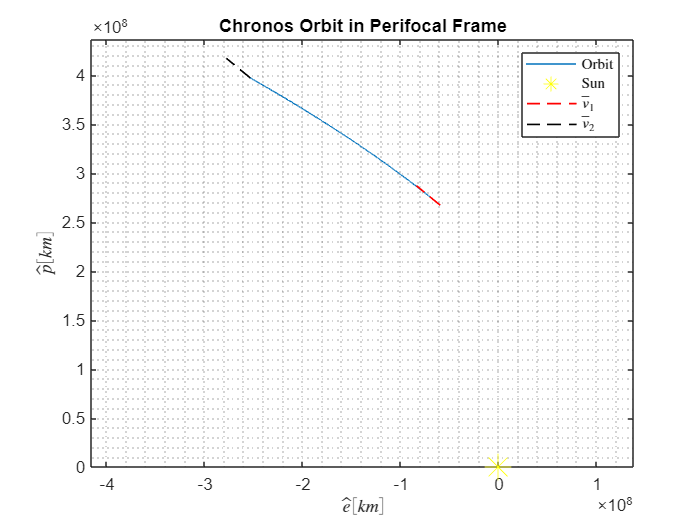

% Hyperbolic anomaly vector
HA      = linspace(H1,H2,5000);

% Initialize vectors
r_P     = zeros(2,length(HA));

for i = 1:length(HA)
    % Calculate current true anomaly 
    theta_star  = 2*atand(sqrt((e+1)/(e-1))*tanh(HA(i)/2));

    % Calculate current radius
    r           = p/(1 + e*cosd(theta_star));

    % Position Vector in Perifocal Frame - Centered at Moon 
    r_P(:,i)  = [r*cosd(theta_star);r*sind(theta_star)];   
end

% Specific angular momentum
h       = sqrt(mu_sun*p);

% Specific energy
energy  = mu_sun/(2*abs(a));

% Velocities
v1      = sqrt(2*(energy + mu_sun/r1));
v2      = sqrt(2*(energy + mu_sun/r2));

% Flight path angles
gamma1  = sign(theta_star1)*acosd(h/(r1*v1));
gamma2  = sign(theta_star2)*acosd(h/(r2*v2));

% Velocity vector in orbit frame
v1_R    = [v1*sind(gamma1) ; v1*cosd(gamma1)];
v2_R    = [v2*sind(gamma2) ; v2*cosd(gamma2)];

% Velocity vector in perifocal frame
v1_P    = [cosd(theta_star1), -sind(theta_star1);...
           sind(theta_star1), cosd(theta_star1)]*v1_R;

v2_P    = [cosd(theta_star2), -sind(theta_star2);...
           sind(theta_star2), cosd(theta_star2)]*v2_R;

figure
plot(r_P(1,:),r_P(2,:))
xlabel('$\hat{e} [km]$' ,'Interpreter','latex')
ylabel('$\hat{p} [km]$','Interpreter','latex')
hold on
plot(0,0,'*y','MarkerSize',16)
ylim([0 1.1*max(r_P(2,:))])
plot([r_P(1,1) (r_P(1,1)+ v1_P(1)*1e6)],[r_P(2,1) (r_P(2,1) + v1_P(2)*1e6)],'--r','LineWidth',1)
plot([r_P(1,end) (r_P(1,end)+ v1_P(1)*1e6)],[r_P(2,end) (r_P(2,end) + v1_P(2)*1e6)],'--k','LineWidth',1)
hold off
axis equal
grid minor
title('Chronos Orbit')
legend('Orbit','Sun','$\bar{v}_1$','$\bar{v}_2$','Interpreter','latex')
title('Chronos Orbit in Perifocal Frame')

**A third tracking strike could help verify a type 1 orbit by using Kepler’s equation for hyperbolic orbits. If we know what time the tracking strike occurs, Kepler’s equation can be used to solve for the hyperbolic anomaly at this time, using the semi-major axis derived assuming a type 1 orbit. With the hyperbolic anomaly determined, the position vector can be calculated (assuming we still know the orbital elements). If the tracking strike matches the calculated position vector, then we can confirm that the orbit is a type 1.**

## Problem 3c)

Find: Perihelion distance of the new asteroid orbit, if there's a chance that Chronos will impact the Earth

% Perihelion distance
rp      = abs(a)*(e - 1);
fprintf('The perihelion distance is %.2f km',rp)

The perihelion distance is 105599969.62 km


$$r_p = |a|(e-1)\\
\\
\mathbf{r_P = 1.0560\times10^8 \ [km] = 0.7059 \ [AU]}$$


**There is a chance that Chronos will impact the Earth, because its perihelion distance is less than 1 AU (the average distance between the Sun and Earth). This means there is a point where Chronos orbit will intersect with Earth's orbit about the Sun (when Chronos orbit radius is about 1 AU), and whether it impacts Earth will depend on the timing of where Earth is in its orbit.**